N = 150;
mu = 0;
std = 18;
lambda = 1.0;

D = eye(N);

n_trials = 1500;
arrDet = zeros(n_trials,1);
for i=1:n_trials
    X1 = normrnd(mu, std, N)/N;
    % X1 = rand(N)/N;
    d1 = det(D - lambda*X1);
    arrDet(i) = d1;
end

% Obtain variance summation
var_arr = zeros(N,1);
for k=1:N
    var_arr(k) = (lambda*std/N)^(2*k)*factorial(N) / factorial(N-k);
end
VarX = sum(var_arr);
[h,p,k,c] = lillietest(log(abs(arrDet)));

EX2 = det(D + std^2*ones(N)/N^2);
% VarX = lambda^2*std^2/N

disp(mean(arrDet));

  -2.8924e+06



disp(var(arrDet));

   5.0884e+16



disp(VarX);

   4.6839e+16



disp('----');

----


disp(p);

    0.1843



disp(mean(log(abs(arrDet))));

   16.1753



disp(sqrt(var(log(arrDet))));

    2.5102



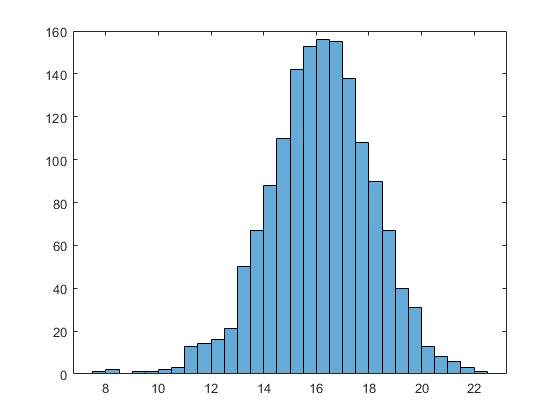

figure
histogram(log(abs(arrDet)));